clear, close all, clc

## Numerische Simulation eines Lungenmodells

In dieser Übung soll ein einfaches Modell einer menschlichen Lunge untersucht werden. 

## Lungenmodell und Modellparameter

Skizzieren und beschreiben sie kurz das einfache, der Analyse zugrundeliegende, Lungenmodell. Erläutern Sie die einzelnen Bestandteile des Ersatzschaltbildes und führen Sie die vorkommenden physiologischen Größen ein. Zeigen Sie deren Parallelen zu elektrischen Netzwerken. Im Modell soll der Strömungswiderstand des Endotrachealtubus R_ID8=4mbarl/s (ID8...Innnendurchmesser 8mm), der Strömungswiderstand der Atemwege (Luftröhre und Bronchien) R=2mbarl/s und die Lungenkapazität C=0,1 l/mbar betragen.

%<ToDo />
R_ID = 4; %Endotrach. Widerstand in mbar
R_aw = 4; %Atemwegswiderstand -..-
R = R_ID + R_aw; %Strömungswiderstand
C = 0.1; %Lungenkap. in l/mbar


Elektrotechnische Größen | Physiologische Größen

- Ursache: Spannung in V | Druckunterschied p in mbar

- Wirkung: Strom i(t) = dq(t) / dt in A | Volumenstrom q(t) = dV(t) / dt in l/s

- Verluste (Spannungsabfall bzw. Druckabfall durch Reibung): Ohmschen Widerstand R = u(t) / i(t) in Ohm                                    Atemwegswiderstand R = p(t) / q(t)

- Energiespeicher (Dehnung): Kapazität C = dq / du in Farrad | Lungenkapazität C = dV / dp in l/mbar                                                         hohe Kapazität -> leicht dehnbar 

Die Ursache für einen Volumenstrom ist der Atemwegsdruck p_aw, der vom Beatmungsgerät erzeugt wird und einem Differenzdruck zum atmosphärischen luftdruck(Maassenpotential) entspricht. EIne menschliche Lunge kann als R-C-Glied modelliert werden. Der Strömungswiderstand R repräsentiert die Reibungsverluste der Gasströmung und entspricht der Reihenschaltung von Tubus (ZUleitung) und Atemweg (Luftröhre & Bronchien) und entspricht dem Verhältnis R = p_R(t) / q(t), wobei p_R(t) dem Druckabfall über dem Strömungswiderstand und q(t) dem Volumenstrom entspricht. Die lUngenkapazität C repräsentiert die Dehnbarkeit der Lunge und entspricht dem Verhältnis c = dV / dp und ist konstant, d.h. der Lungendruck ist dem Lungenvolumen direkt propotional.

## Numerische Berechnung des Füllvorganges

In der zu simulierenden Inspirationsphase soll ein Tidalvolumen von V_T=500ml in die Lungen eingebracht werden. Der Füllvorgang der Lunge (Volumenstrom, Lungendruck) ist für eine Beatmung mit konstantem Atemwegsdruck P_aw (druckkontrollierte Beatmung) und auf Basis des entwickelten Lungenmodells numerisch zu berechnen und dem theoretischen zu erwartenden Verläufen gegenüberzustellen. 

Zur numerischen Berechnung wird das Systemsverhalten in kurzen Zeitintervalle betrachtet - in gleicher Weise Arbeiten professionelle Simulationswerkzeuge wie z.B. Mutlisim. Werden die Zeitspannen klein genug gewählt, so verändern sich die die Drücke und der Fluss innerhalb der Zeitintervalle nur wenig und können als annähernd konstant angeonmmen werden - in kurzer Zeit kann nur wenig Gas in die Lunge einströmen, weshalb der Lungendruck sich auch nur wenig ändert. Die Annahme von konsanten Größen vereinfacht die Berechnung erheblich, sodass lediglich einfache mathematische Operationen zur Berechnung der Größen im aktuellen Zeitintervall und den neuen Größen im nächsten Zeitintervall notwendig sind. Das Resultat ist ein stückweise stetige Näherung des zeitlichen Verlaufs der einzelnen Größen - mathematisch spricht man von einer sogenannten Differenzengleichung. Der exakte zeitliche Verlauf entspricht der Lösung einer linearen Differentialgleichung erster Ordnung (RC-Glied) mit konstanter Störfunktion.

Berechnen Sie den zum Einbringen des Tidalvolumens notwendigen Atemwegsdruck P_aw.

%<ToDo />
V_T = 0.5; % Tidalvolumen in l
P_aw = V_T / C; %Atemwegsdruck in mbar

Berechnen Sie die zu erwartende Simulationszeit t_end sowie die Dauer eines Intervalls dt, wenn die unterschiedlichen physiologischen Größen Volumenfluss q(t_n) und diverse Drücke p(t_n) für N zeitlich äquidistante Stützstellen t_n=n*dt berechnet werden sollen.

%<ToDo />
T1 = R * C; %Zeitkonstante in s
t_end = 10 * T1; %Simulationszeit in s
N = 200; %Anzahl der Zeitschritte
dt = t_end / (N-1); %Intervalldauer in s

Initialisieren Sie das Anfangsvolumen der Lunge. Implementieren Sie die Berechnungsschritte zur Ermittlung sämtlicher Drücke und des aktuellen Volumenstroms innerhalb eines Zeitintervalls. Berechnen Sie das neue Lungenvolumen am Ende des aktuellen Zeitintervalls und verwenden Sie das aktualisierte Volumen in einer Interation um denselben Vorgang für alle Zeitintervalle zu wiederholen. Speichern Sie die Werte der Drücke und des Volumenstroms in 1D-Arrays, d.h. als Vektoren (vT...Zeit, vV_L...Lungenvolumen, vP_L...Lungendruck, vP_R...Atemwegsdruck, vQ...Volumenstrom).

%<ToDo />
vV_L(1) = 0; %Startvolumen der Lunge

for n = 1:N
    vT(n) = (n-1) * dt; %Aktuelle Simulationszeit
    vP_L(n) = vV_L(n)/C; %Lungendruck in mbar
    
    w = 1/T1;
    vP_aw(n) = P_aw + P_aw/2 *sin(w * vT(n));
    vP_R(n) = vP_aw(n) - vP_L(n); %paw = p_R + p_l --> p_R = paw - p_L
    vQ(n) = vP_R(n) / R; %R = p_R / q --> q = p_R / R "Ohmsche Gesetz"
    dV = vQ(n) * dt; %q = dV / dt --> dV = q * dt
    vV_L(n+1) = vV_L(n) + dV; %aktualisiertes Lungenvol. nach dem Zeitintervall dt
end

## Theoretische Lösung

Berechnen sie die exakten Werte für die Stützstellen zu den Zeitpunkten vT(n) mit der bekannte Lösung der DGL (Kondensatorladekurve).

%<ToDo />
vP_L_th = P_aw * (1-exp(-vT /T1));
vV_L_th = C * vP_L_th;
Qmax = P_aw / R;
vQ_th = Qmax * exp(-vT/T1);

## Grafische Darstellungen

Stellen Sie den zeitlichen Verlauf des Volumenstroms (oben) und des Lungendrucks (unten) mittels zweier Diagramme dar. Stellen Sie jeweils den Verlauf der numerischen Näherung und den exakten theoretischen Verlauf (strichliert) dar.

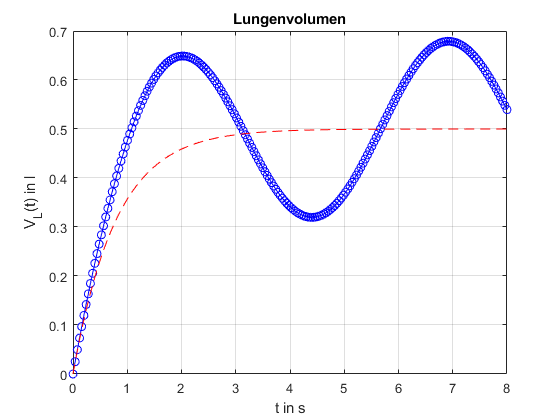

%<ToDo />
plot(vT, vV_L(1:end-1), 'b-o', vT, vV_L_th, 'r--'), title('Lungenvolumen')
xlabel('t in s'), ylabel('V_L(t) in l'), grid on

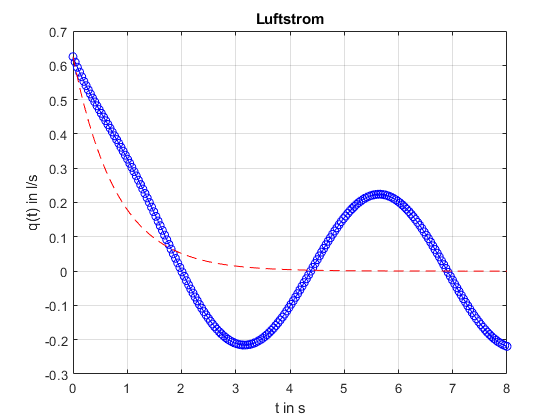

plot(vT, vQ, 'b-o', vT, vQ_th, 'r--'), title('Luftstrom')
xlabel('t in s'), ylabel('q(t) in l/s'), grid on

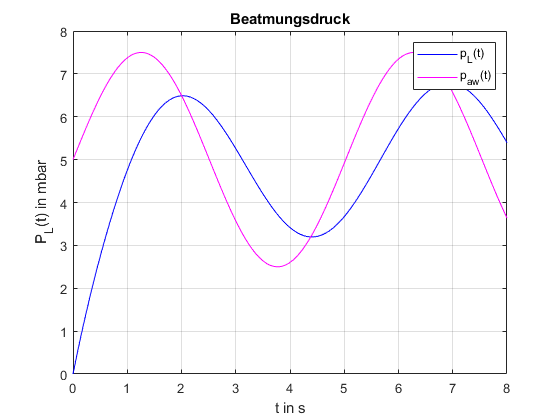

plot(vT, vP_L, 'b-', vT, vP_aw, 'm-'), title('Beatmungsdruck')
xlabel('t in s'), ylabel('P_L(t) in mbar'), grid on
legend('p_L(t)', 'p_{aw}(t)')